% ID number: 2021200687
% Name:      唐金峰
% Date:      Nov 25, 2021(modified)
load test2021.mat

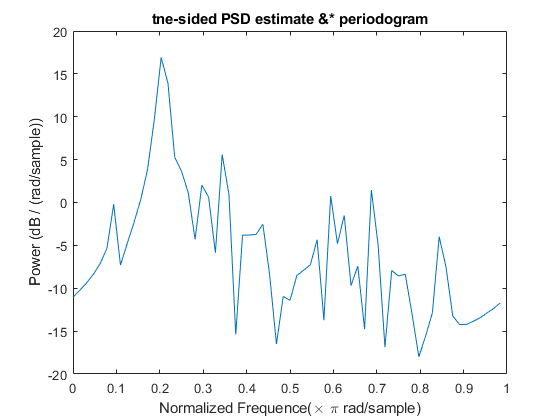

% 周期图
x = test2021;
[pxx, f] = periodogram(x,[],64,1); 
% For complex-valued signals, f spans the interval [0,fs)
plot(f,10*log10(pxx));
xlabel('Normalized Frequence(\times \pi rad/sample)')
ylabel('Power (dB / (rad/sample))')
title('tne-sided PSD estimate &* periodogram')

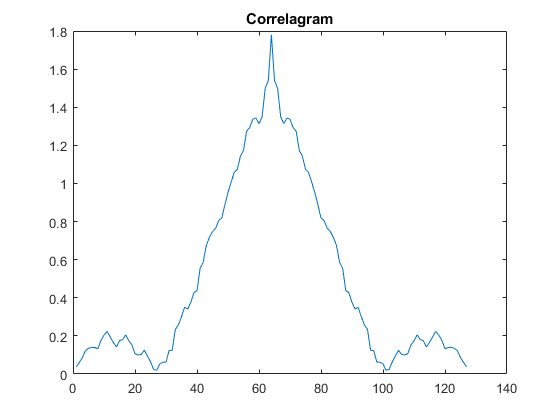

% 计算 rxx_complex
rxx = zeros(64,1);
rxx(1) = dot(x,x);
for i = 1 : length(rxx)-1
    x_lag  = circshift(x,-i);
    x_lag(end-i+1:end) = 0;
    rxx(i+1)= dot(x,x_lag);
end
rxx = rxx./length(x);
rxx_complex = [conj(flip(rxx(2:end))); rxx];
assert(rxx_complex(1) == conj(rxx_complex(end)),'conjugate btw rxx[-63] and rxx[63]')
assert(isreal(rxx_complex(64)),'Real rxx[0]')
plot(abs(rxx_complex))
title('Correlagram')

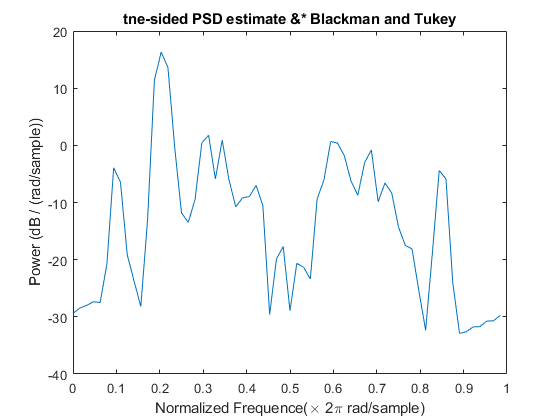

% Blackman and Tukey
[pxx, f] = periodogram(x,hamming(64),64,1); 
% For complex-valued signals, f spans the interval [0,fs)
plot(f,10*log10(pxx));
xlabel('Normalized Frequence(\times 2\pi rad/sample)')
ylabel('Power (dB / (rad/sample))')
title('tne-sided PSD estimate &* Blackman and Tukey')

% periodogram(x,hann(64),64)

Bartlett-Hann 窗 [`barthannwin`](https://ww2.mathworks.cn/help/signal/ref/barthannwin.html)

Bartlett 窗 [`bartlett`](https://ww2.mathworks.cn/help/signal/ref/bartlett.html)

Hamming 窗 [`hamming`](https://ww2.mathworks.cn/help/signal/ref/hamming.html)

Hann 窗 [`hann`](https://ww2.mathworks.cn/help/signal/ref/hann.html)

`https://www.mathworks.com/help/signal/ug/windows.html`

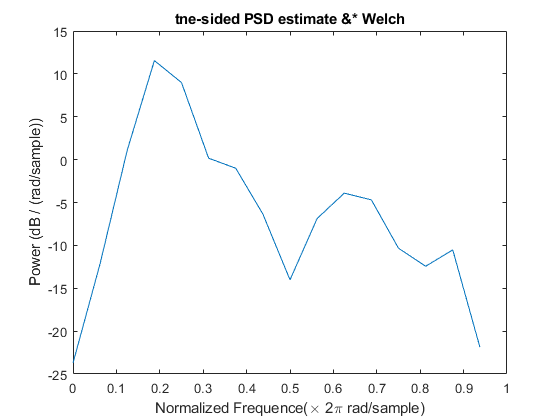

segmentLength = 16;
nfft = 16;
% pxx = pwelch(x,segmentLength,[],nfft);
[pxx, f] = pwelch(x,segmentLength,[],nfft,1);
plot(f, 10*log10(pxx))
xlabel('Normalized Frequence(\times 2\pi rad/sample)')
ylabel('Power (dB / (rad/sample))')
title('tne-sided PSD estimate &* Welch')

% % 太阳黑子数据
% load sunspot.dat
% relNums=sunspot(1:256,2);
% [px,f] = periodogram(relNums,[],256,1); % fs = 2*pi
% % For real-valued signals, f spans the interval 
% % [0,fs/2] when nfft is even and [0,fs/2) when nfft is odd
% plot(f,10*log10(px))
% xlabel('Cycles/Year')
% ylabel('dB / (Cycles/Year)')
% title('one-sided PSD estimate of Relative Sunspot')

% % 测试用例
% rng(1); % For reproducibility
% y = randn(1000, 1);
% [normalizedACF, lags] = autocorr(y,'NumLags',10,'NumSTD',0.);
% unnormalizedACF = normalizedACF*var(y,1); % 无偏方差
% [lags  normalizedACF  unnormalizedACF]